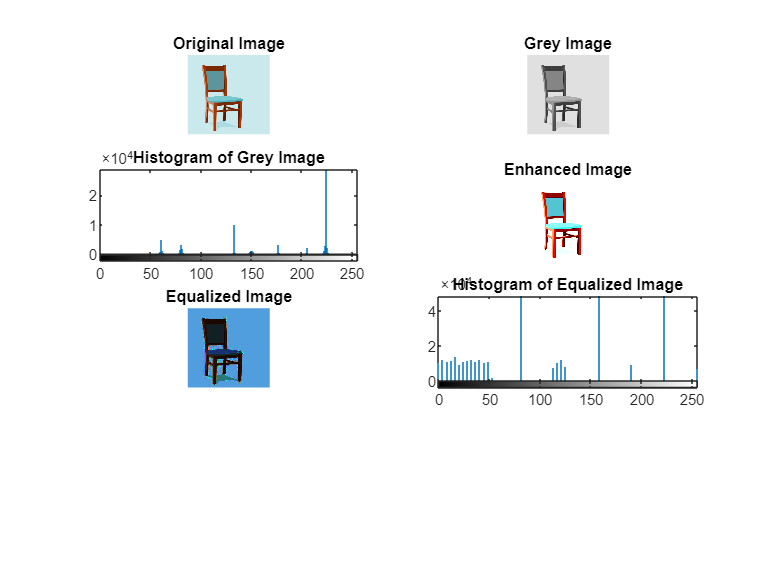

% Simulation and display of contrast stretching
% of a low contrast image, Histogram and Histogram
% equalization
clc

i=imread("original image.jpg");

subplot(4,2,1);
imshow(i);
title('Original Image');

subplot(4,2,2);
greyi=rgb2gray(i);
imshow(greyi);
title('Grey Image');

subplot(4,2,3);
imhist(greyi);
title('Histogram of Grey Image');


subplot(4,2,4);
a=imadjust(i,[.2 .7],[]);
imshow(a);
title('Enhanced Image');


subplot(4,2,5);
c=histeq(i);
imshow(c);
title('Equalized Image');

subplot(4,2,6);
imhist(c);
title('Histogram of Equalized Image');